# COVID-19 Highlights

***[Last Updated July 22, 2020]***

## The Numbers at a Glance

% Use https://www.sejda.com/html-to-pdf to print to one long pdf
load_data_us;
usstates.data_4 = data_4;
usstates.deaths = deaths;
usstates.popu = popu;
usstates.lats = lats;
usstates.longs = longs;
usstates.countries = countries;

load_data_global;
allcountries.data_4 = data_4;
allcountries.deaths = deaths;
allcountries.popu = popu;
allcountries.lats = lats;
allcountries.longs = longs;
allcountries.countries = countries;

load_data_county;


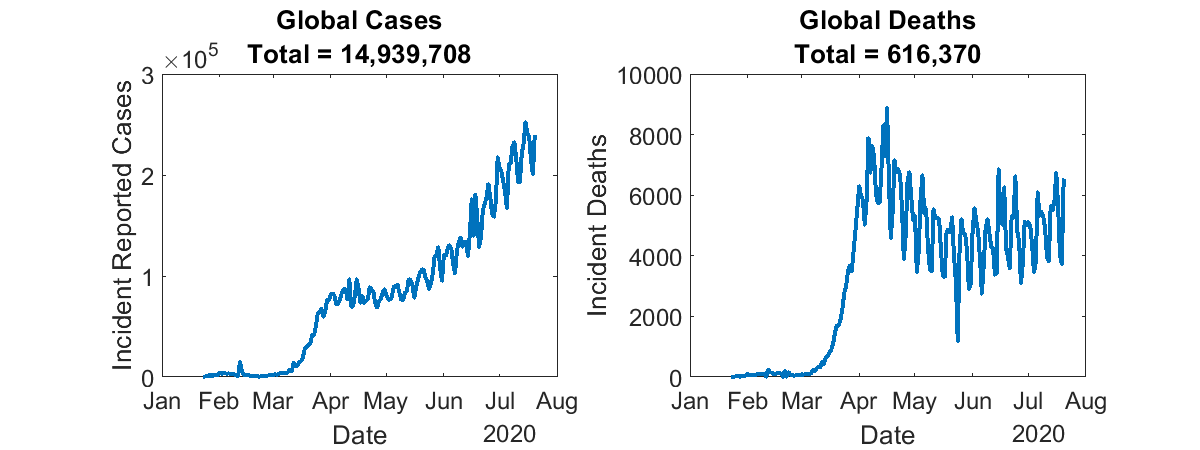

figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])
subplot(1, 2, 1);
offset = 1;
trueshow = (offset:size(data_4, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(sum(allcountries.data_4(:, trueshow), 1)), 'LineWidth', 3);
xlabel('Date');
ylabel('Incident Reported Cases');
title({'Global Cases'; ['Total = ' addComma(sum(allcountries.data_4(:, end)))]});
subplot(1, 2, 2);
offset = 1;
trueshow = (offset:size(data_4, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(sum(allcountries.deaths(:, trueshow), 1)), 'LineWidth', 3);
xlabel('Date');
ylabel('Incident Deaths');
title({'Global Deaths'; ['Total = ' addComma(sum(allcountries.deaths(:, end)))]});

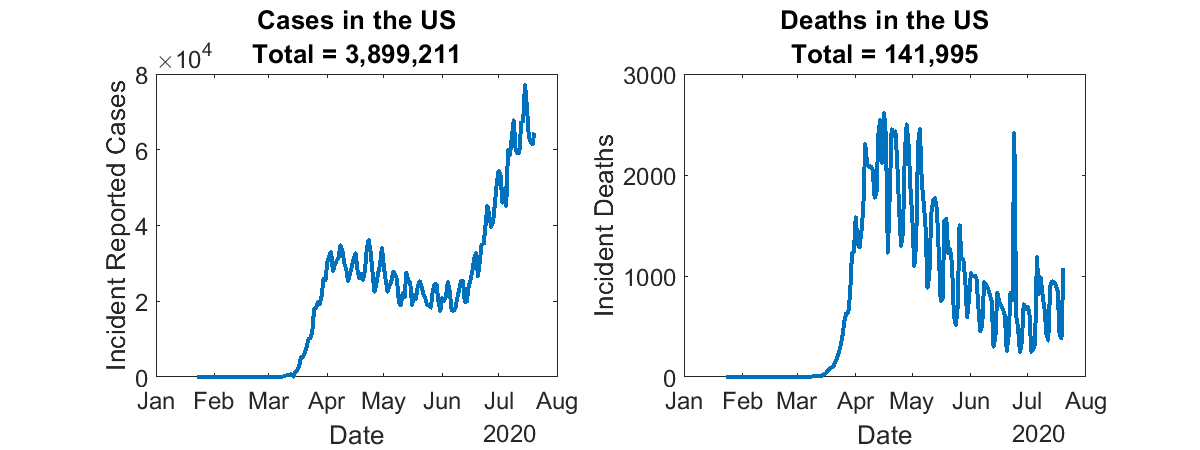

figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])
subplot(1, 2, 1);
offset = 1;
trueshow = (offset:size(data_4, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(sum(allcountries.data_4(156, trueshow), 1)), 'LineWidth', 3);
xlabel('Date');
ylabel('Incident Reported Cases');
title({'Cases in the US'; ['Total = ' addComma(sum(allcountries.data_4(156, end)))]});
subplot(1, 2, 2);
offset = 1;
trueshow = (offset:size(data_4, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(sum(allcountries.deaths(156, trueshow), 1)), 'LineWidth', 3);
xlabel('Date');
ylabel('Incident Deaths');
title({'Deaths in the US'; ['Total = ' addComma(sum(allcountries.deaths(156, end)))]});

## COVID-19 on the Map

Which regions are seeing an increase in new cases and which ones are seeing a decrease? In the following maps, the size of the bubble represents the number of reported cases in the region (country or county). The orange colored bubbles represent an increase in the weekly number of new cases. The blue colored bubbles represent a decrease in the weekly number of new cases. 

### The World

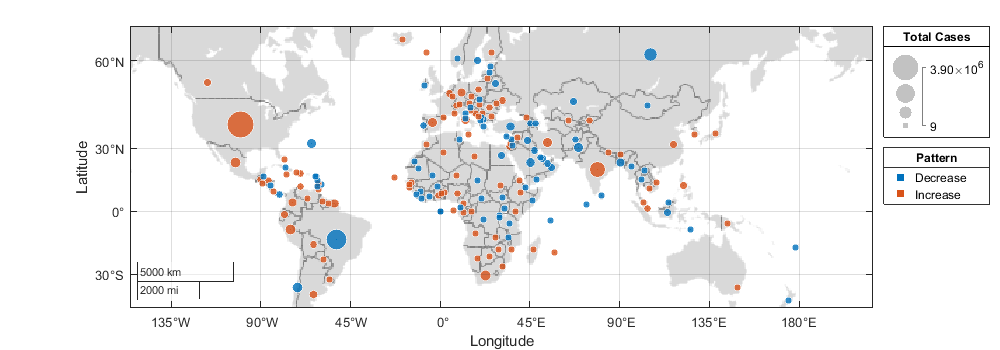

maxt = size(allcountries.data_4, 2);
inc_measure = (allcountries.data_4(:, maxt) -  allcountries.data_4(:, maxt-7)) > (allcountries.data_4(:, maxt-7) -  allcountries.data_4(:, maxt-14));
%figure('DefaultAxesFontSize',10);
figure;
set(gcf,'position',[1,1,1000,350]);
gb = geobubble(allcountries.lats, allcountries.longs, allcountries.data_4(:, end), categorical(inc_measure, [0 1], {'Decrease', 'Increase'}));
gb.SizeLegendTitle = 'Total Cases';
gb.ColorLegendTitle = 'Pattern';
gb.Basemap = 'grayland';

### The counties of the US 

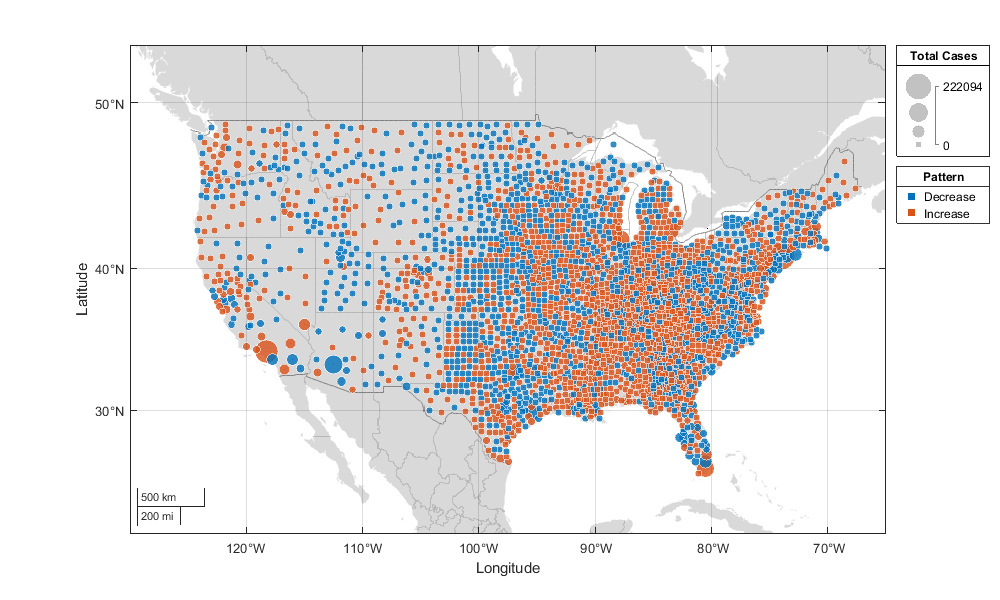

maxt = size(data_4, 2);
inc_measure = (data_4(:, maxt) -  data_4(:, maxt-7)) > (data_4(:, maxt-7) -  data_4(:, maxt-14));
figure;
set(gcf,'position',[1,1,1000,600]);
gb = geobubble(FIP_data.Lat, FIP_data.Long_, data_4(:, end), categorical(inc_measure, [0 1], {'Decrease', 'Increase'}));
geolimits([25 50], [-130 -65]);
gb.SizeLegendTitle = 'Total Cases';
gb.ColorLegendTitle = 'Pattern';
gb.Basemap = 'grayland';

## Dynamic Reproduction Number

The Dynamic Reproduction Number (**Rt**) measures the potential speed of the epidemic.It measures the average number of new infections created by one infected individual. An epidemic will rise quickly if each infected individual were to create more than one infections, i.e., Rt > 1. On the other hand, if each infected individual creates less than one infection on an average. i.e., Rt < 1, the epidemic will slow down and die out.

**Note:** Rt is "learned" from a model. Therefore, the numbers you see here may differ slightly from those shown by other sources due to difference in modeling techniques.

### Latest Reproduction Number on the World Map

The following map shows the potential severity in all the countries, measured in terms of where the latest Rt value stands for each country. In addition, the size of the bubbles represents the number of new cases in the last week.

A red bubble is likely to expand, while a green bubble is likely to shrink in the near future.

The ideal scenario should be a small green bubble, suggesting that the epidemic is close to disappearing. On the other hand, the worst scenario would be a large red bubble, which would indicate that even though a large number of new cases have been seen recently, this number is likely to further increase.

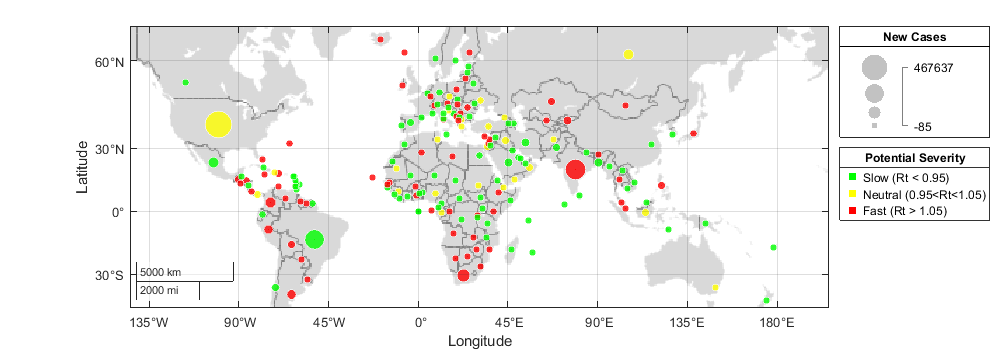

Rt_tab = readtable('../results/scores/global_Rt_num.csv');
allRt = Rt_tab{2:end, end};
figure;
set(gcf,'position',[1,1,1000,350]);
Rtcats = zeros(length(allcountries.popu), 1);
Rtcats(allRt<0.95) = -1;
Rtcats(allRt>1.05) = 1;
gb = geobubble(allcountries.lats, allcountries.longs, allcountries.data_4(:, end) - allcountries.data_4(:, end-7), categorical(Rtcats, [-1 0 1], {'Slow (Rt < 0.95)', 'Neutral (0.95<Rt<1.05)', 'Fast (Rt > 1.05)'}), 'BubbleColorList', {'g', 'y', 'r'});
gb.SizeLegendTitle = 'New Cases';
gb.ColorLegendTitle = 'Potential Severity';
gb.Basemap = 'grayland';

### Latest Reproduction Number on the US Map

The following map shows the same for the US states.

**Note:** We show the potential severity at the state-level instead of county level, as the Reprodcution Number can be more reliably learned at the state-level compared to the county-level.

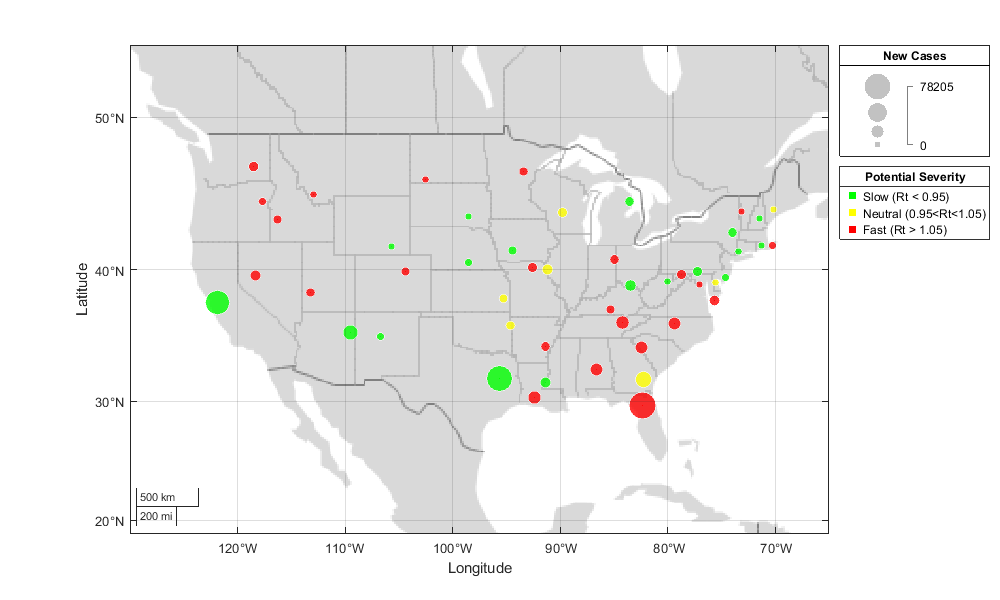

Rt_tab = readtable('../results/scores/us_Rt_num.csv');
allRt = Rt_tab{2:end, end};
figure;
set(gcf,'position',[1,1,1000,600]);
Rtcats = zeros(length(usstates.popu), 1);
Rtcats(allRt<0.95) = -1;
Rtcats(allRt>1.05) = 1;
gb = geobubble(usstates.lats, usstates.longs, usstates.data_4(:, end) - usstates.data_4(:, end-7), categorical(Rtcats, [-1 0 1], {'Slow (Rt < 0.95)', 'Neutral (0.95<Rt<1.05)', 'Fast (Rt > 1.05)'}), 'BubbleColorList', {'g', 'y', 'r'});
geolimits([25 50], [-130 -65]);
gb.SizeLegendTitle = 'New Cases';
gb.ColorLegendTitle = 'Potential Severity';
gb.Basemap = 'grayland';

### Reproduction Numbers of Countries Over Time

The boxplot below shows the median Dynamic Reproduction Number (Rt) of all countries. The Rt values for all the countries on a given week are distributed over a vertical line. The center of the line is the median value over all the countries along with the thick line representing the 25th and 75th percentile.

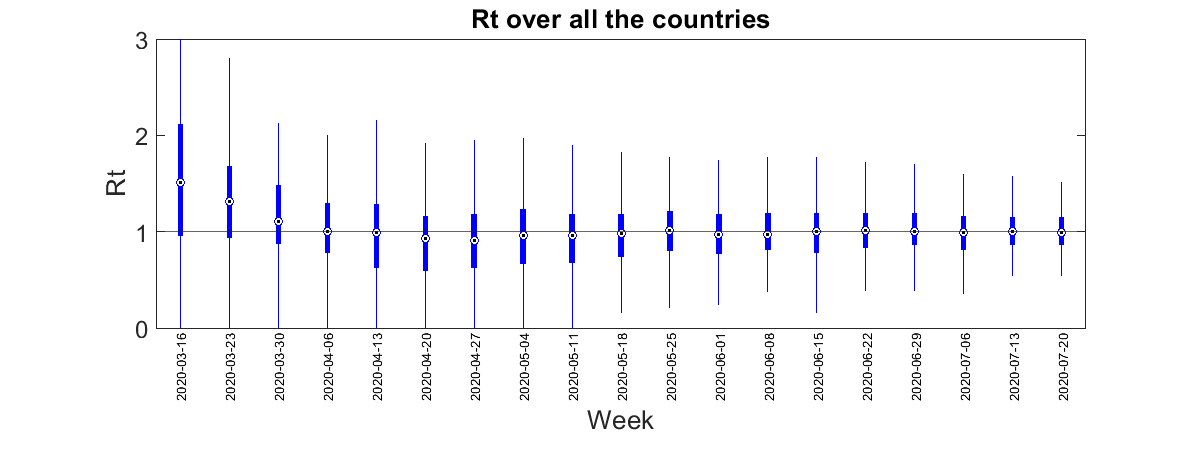

Rt_tab = readtable('../results/scores/global_Rt_num.csv');
Rt_us = Rt_tab{2:end, 3:end};
% countries = Rt_tab{2:end, 2};
% Rt_tab = readtable('../results/scores/us_Rt_conf.csv');
% Rt_dev = Rt_tab{2:end, 3:end};
figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])

Tx = datetime(2020, 1, 21)+caldays(55:7:55+7*(size(Rt_us, 2)-1));
datecols= datestr(Tx, 'yyyy-mm-dd');
datecols = cellstr(datecols);

boxplot(Rt_us, datecols,'PlotStyle','compact', 'symbol','');
%cid = 3; errorbar((Rt_us(cid, :)), Rt_dev(cid, :));
yline(1);
title('Rt over all the countries');
xlabel('Week');
ylabel('Rt');
ylim([0, 3]);

### Reproduction Numbers of US States Over Time

The boxplot below shows the median Dynamic Reproduction Number of all US states along with the thick line representing the 25th and 75th percentile. A value of Rt below 1 on a given week implies that if the trends were to continue, the epidemic would have slowed down.

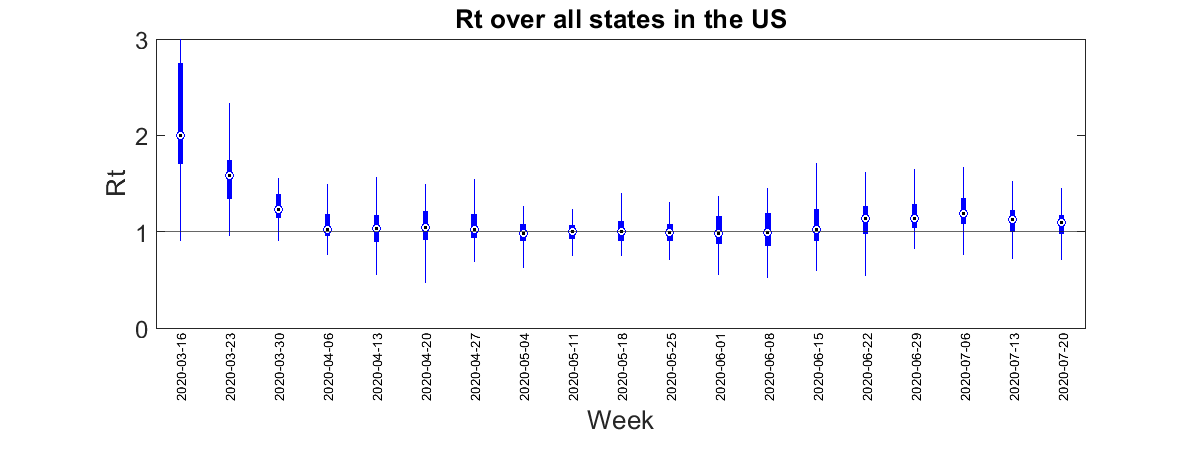


Rt_tab = readtable('../results/scores/us_Rt_num.csv');
Rt_us = Rt_tab{2:end, 3:end};
%countries = Rt_tab{2:end, 2};
% Rt_tab = readtable('../results/scores/us_Rt_conf.csv');
% Rt_dev = Rt_tab{2:end, 3:end};
figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])

Tx = datetime(2020, 1, 21)+caldays(55:7:55+7*(size(Rt_us, 2)-1));
datecols= datestr(Tx, 'yyyy-mm-dd');
datecols = cellstr(datecols);

boxplot(Rt_us, datecols,'PlotStyle','compact', 'symbol','');
%cid = 3; errorbar((Rt_us(cid, :)), Rt_dev(cid, :));
yline(1);
title('Rt over all states in the US');
xlabel('Week');
ylabel('Rt');
ylim([0, 3]);

## Model-based Case Fatality Rate

Case Fatality Rate (CFR) measures the number of deaths per reported case (per 100 reported cases when displayed as a percentage). However, it does not precisely indicate the chances of a reported case leading to a death, as their is a lag between an individual being positive and then dying. For instance, if a region has recently seen a fast rise in the positive cases, then it is likely that many deaths will be reported in the next few weeks but have not been observed yet. CFR will underestimate the probability of death in such a scenario.

Here, we show Model-based Case Fatality Rate (MFR), which measures the probability of a reported case leading to a death. Note that this is learned using our model, and other sources may report slightly different results.

### MFR on the World Map

The following map shows the expected fatality measured in terms of where the latest MFR value stands for each country. In addition, the size of the bubbles represents the number of new cases in the last week.

A large red bubble is the worst case, which is expected to lead to large number of deaths.

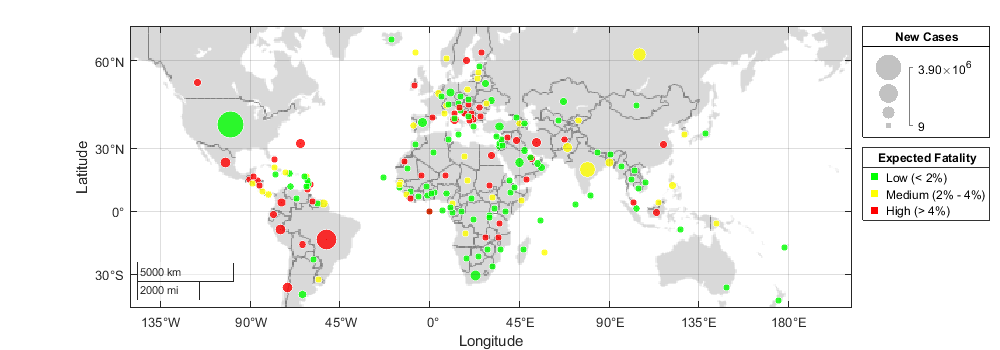

Rt_tab = readtable('../results/scores/global_MFR_num.csv');
allRt = Rt_tab{2:end, end};
nanidx = isnan(allRt);
allRt(nanidx) = allcountries.deaths(nanidx, end)./allcountries.data_4(nanidx, end);
figure;
set(gcf,'position',[1,1,1000,350]);
Rtcats = zeros(length(allcountries.popu), 1);
Rtcats(allRt<0.02) = -1;
Rtcats(allRt>0.04) = 1;
gb = geobubble(allcountries.lats, allcountries.longs, allcountries.data_4(:, end), categorical(Rtcats, [-1 0 1], {'Low (< 2%)', 'Medium (2% - 4%)', 'High (> 4%)'}), 'BubbleColorList', {'g', 'y', 'r'});
gb.SizeLegendTitle = 'New Cases';
gb.ColorLegendTitle = 'Expected Fatality';
gb.Basemap = 'grayland';

### MFR on the US Map

The following shows the same for the US states.

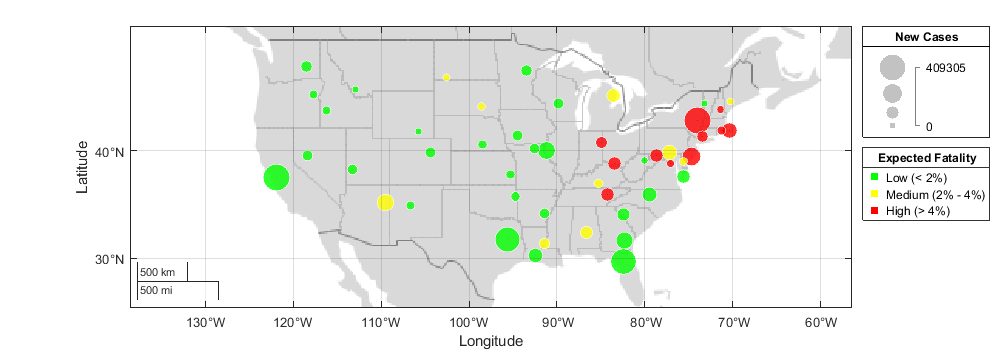

Rt_tab = readtable('../results/scores/us_MFR_num.csv');
allRt = Rt_tab{2:end, end};
nanidx = isnan(allRt);
allRt(nanidx) = usstates.deaths(nanidx, end)./usstates.data_4(nanidx, end);
figure;
set(gcf,'position',[1,1,1000,350]);
Rtcats = zeros(length(usstates.popu), 1);
Rtcats(allRt<0.02) = -1;
Rtcats(allRt>0.04) = 1;
gb = geobubble(usstates.lats, usstates.longs, usstates.data_4(:, end), categorical(Rtcats, [-1 0 1], {'Low (< 2%)', 'Medium (2% - 4%)', 'High (> 4%)'}), 'BubbleColorList', {'g', 'y', 'r'});
geolimits([25 50], [-130 -65]);
gb.SizeLegendTitle = 'New Cases';
gb.ColorLegendTitle = 'Expected Fatality';
gb.Basemap = 'grayland';